MEM703039 - KỸ THUẬT ROBOT

LỚP: N01.TH1

Thực hành: Lab 4

Mã số sv:

Họ và tên:

clear all
clc

Viết chương trình tính ma trận quay

%Cách 1: sử dụng số 
% alpha = pi/6
% beta = -pi/3
% gamma = pi/4

% Cách 2
syms alpha beta gamma

% Ma trận quay quanh trục X một góc alpha

RotationX = [1    0            0; ...
             0 cos(alpha)   -sin(alpha); ...
             0 sin(alpha)    cos(alpha)]

$$RotationX = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

% Ma trận quay quanh trục Y một góc beta

RotationY = [cos(beta)    0   sin(beta); ...
             0            1   0; ...
             -sin(beta)   0   cos(beta)]

$$RotationY = \left(\begin{array}{ccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right)\\ 0 & 1 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) \end{array}\right)$$

% Ma trận quay quanh trục Z một góc gamma

RotationZ = [cos(gamma)   -sin(gamma)   0; ...
             sin(gamma)   cos(gamma)    0; ...
             0            0             1]

$$RotationZ = \left(\begin{array}{ccc} \cos\left(\gamma \right) & -\sin\left(\gamma \right) & 0\\ \sin\left(\gamma \right) & \cos\left(\gamma \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R = RotationZ * RotationY * RotationX

$$R = \left(\begin{array}{ccc} \cos\left(\beta \right)\,\cos\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right)-\cos\left(\alpha \right)\,\sin\left(\gamma \right) & \sin\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)+\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right)-\cos\left(\gamma \right)\,\sin\left(\alpha \right)\\ -\sin\left(\beta \right) & \cos\left(\beta \right)\,\sin\left(\alpha \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$

simplify(R) % rút gọn

$$ans = \left(\begin{array}{ccc} \cos\left(\beta \right)\,\cos\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\alpha \right)\,\sin\left(\beta \right)-\cos\left(\alpha \right)\,\sin\left(\gamma \right) & \sin\left(\alpha \right)\,\sin\left(\gamma \right)+\cos\left(\alpha \right)\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\cos\left(\gamma \right)+\sin\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\alpha \right)\,\sin\left(\beta \right)\,\sin\left(\gamma \right)-\cos\left(\gamma \right)\,\sin\left(\alpha \right)\\ -\sin\left(\beta \right) & \cos\left(\beta \right)\,\sin\left(\alpha \right) & \cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$

Sử dụng Robotics Toolbox

a = pi/6

a = 0.5236

b = -pi/3

b = -1.0472

c = pi/4

c = 0.7854

R1 = rotx(a) 

R1 =     1.0000         0         0
         0    1.0000   -0.0091
         0    0.0091    1.0000


R2 = roty(b)

R2 =     0.9998         0   -0.0183
         0    1.0000         0
    0.0183         0    0.9998


R3 = rotz(c)

R3 =     0.9999   -0.0137         0
    0.0137    0.9999         0
         0         0    1.0000



T = transl(1,0,0) * trotx(pi/2)* transl(0,1,0)

T =     1.0000         0         0    1.0000
         0    0.9996   -0.0274    0.9996
         0    0.0274    0.9996    0.0274
         0         0         0    1.0000


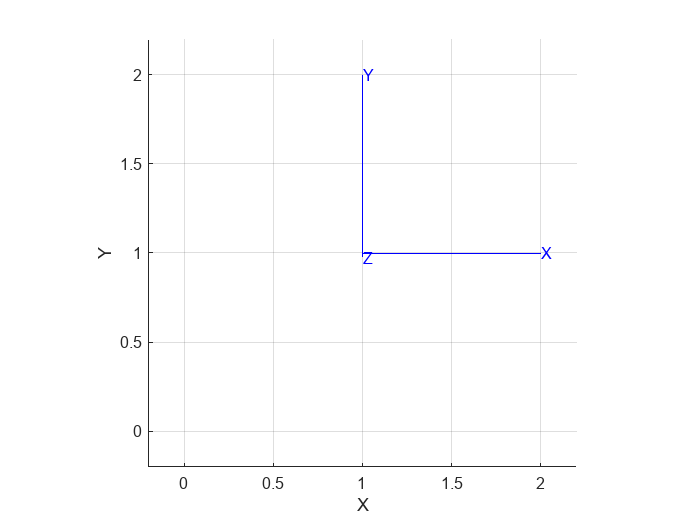

trplot(T)

R = t2r(T)

R =     1.0000         0         0
         0    0.9996   -0.0274
         0    0.0274    0.9996


P = transl(T)'

P =     1.0000    0.9996    0.0274


Bài toán động học thuận Robot

VD: Robot 3 bậc tự do dạng RRR (3 khớp quay)

Chú ý: Code chỉ dùng để tham khảo cách viết code

clc;
clear;

% Thông số Denavit-Hartenberg (DH)
syms theta1 theta2 theta3 a1 a2 a3

% Hàm chuyển đổi DH
DH = @(theta, d, a, alpha) [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
                            sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
                                  0,             sin(alpha),             cos(alpha),            d;
                                  0,                    0,                     0,            1];

% Ma trận chuyển đổi từ hệ quy chiếu khớp này sang khớp tiếp theo
T1 = DH(theta1, 0, a1, 0);  % Ma trận chuyển đổi từ khớp 1 đến khớp 2
T2 = DH(theta2, 0, a2, 0);  % Ma trận chuyển đổi từ khớp 2 đến khớp 3
T3 = DH(theta3, 0, a3, 0);  % Ma trận chuyển đổi từ khớp 3 đến khâu thao tác

% Ma trận chuyển đổi tổng thể từ gốc đến điểm thao tác
T = simplify(T1 * T2 * T3);

% Hiển thị kết quả
disp('Ma trận chuyển đổi đồng nhất từ gốc đến đầu cuối:');

Ma trận chuyển đổi đồng nhất từ gốc đến đầu cuối:


disp(T);

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+a_{3}\,\sigma_{2}\\ \sigma_{1} & \sigma_{2} & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)+a_{3}\,\sigma_{1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$


% Vị trí của khâu thao tác (end-effector) trong không gian
position = T(1:3, 4);
disp('Vị trí của đầu cuối:');

Vị trí của đầu cuối:


disp(position);

$$\left(\begin{array}{c} a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)+a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 \end{array}\right)$$